close all;
clear;

# Analisi esplorativa 

load ws_steak.mat
%data_m

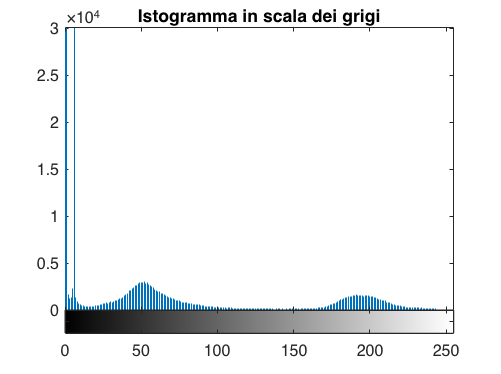

% Istogramma in scala dei grigi
figure
imhist(s1)
title('Istogramma in scala dei grigi')

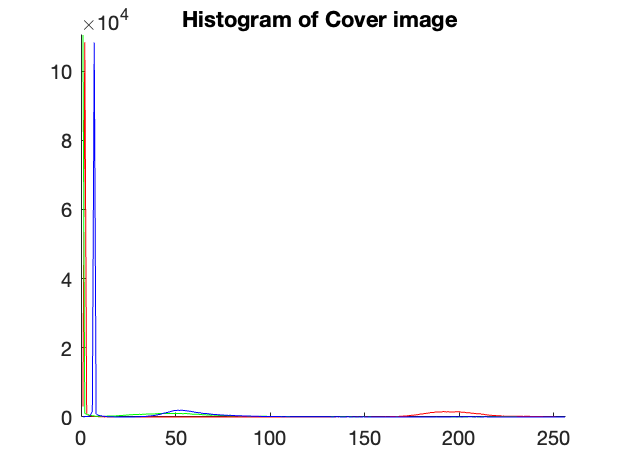


% Istogramma diviso per colore
figure

Red = s1(:,:,1);
Green = s1(:,:,2);
Blue = s1(:,:,3);
%Get histValues for each channel
hold on;

xlim ([0, inf]);
ylim ([0, inf]); 
plot(imhist(Red), 'r');
plot(imhist(Green), 'g');
plot(imhist(Blue), 'b');

%plot(x, yRed, 'Red');
title('Histogram of Cover image ');  

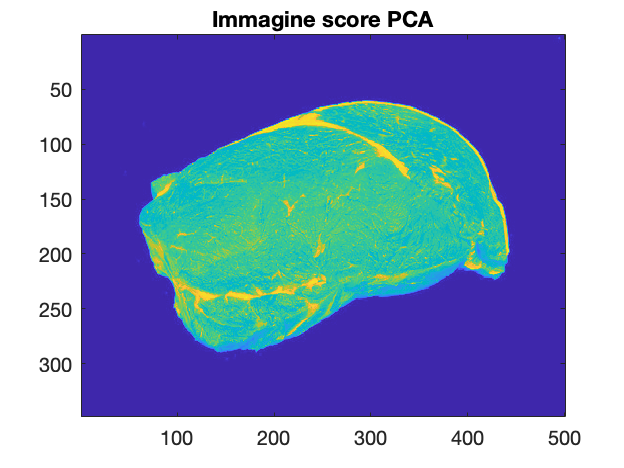



% Immagine scores pca
figure
imagesc(reshape(SCORES_PC1(:,1), 348, 500, 1))
title('Immagine score PCA')

% Loadings

figure
hold on;
xlim([0.5, 3]);
scatter(1, loadingsPC1(1,1), 'red', 'filled');
scatter(2, loadingsPC1(2,1), 'green', 'filled');
scatter(3, loadingsPC1(3,1), 'blue', 'filled');
title('Loadings')

# PCA Esplorativa

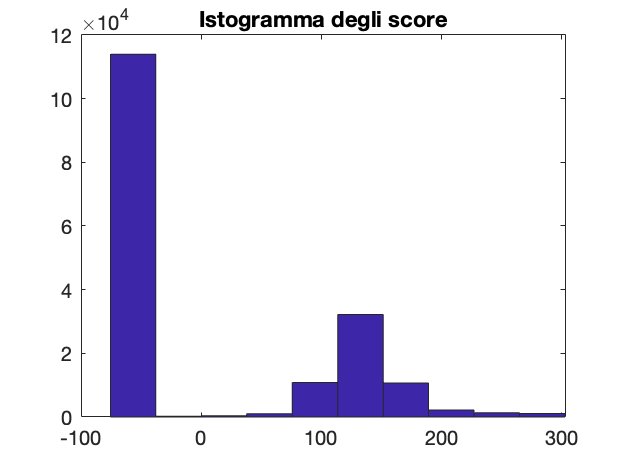

figure
hist(SCORES_PC1)
title('Istogramma degli score');

% Histogramma T2-Q

%figure
%scatter(HotellingT2S1(:, 1), QResidualS1(:, 1));
%xlabel('Hotelling T^2');
%ylabel('Q Residual');

# Clustering

## Calcolo della silhouette per kmeans

Confronto tra distanza sqEuclidea e manhattan con e senza autoscale.

evaSqEuclidean = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattan = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
evaSqEuclideanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
eva_t = [evaSqEuclidean.CriterionValues, evaManhattan.CriterionValues, evaSqEuclideanAutoscale.CriterionValues, evaManhattanAutoscale.CriterionValues];


name = categorical({'sqEuclidean';'Manhattan'; 'sqEuclidean Autoscale'; 'Manhattan Autoscale'}); 
figure
bar(name,eva_t)

## K-Means calcolato con le due distanze

idxSqEuclide = kmeans(s1_unf, 3, "Distance","sqeuclidean");
idxManhattan = kmeans(s1_unf, 3, "Distance", "cityblock");
idxSqEuclideAutoscale = kmeans(s1_unf_autoscale.data, 3, "Distance", "sqeuclidean");
idxManhattanAutoscale = kmeans(s1_unf_autoscale.data, 3, "Distance", "cityblock");

## Evidenziamo il grasso

idxKMeans = [idxSqEuclide, idxManhattan, idxSqEuclideAutoscale, idxManhattanAutoscale];

clear num_class_grasso;
figure
imagesc(uint8(reshape(s1_unf, 348, 500,3)));

kmeans_img = double(reshape(s1,348*500,3));

pixel_grasso = [];
for i=1:4
    num_class_grasso = 0;
    
    len_class1 = 0;
    len_class2 = 0;
    len_class3 = 0;
    idx = idxKMeans(:,i);
    
    for j = 1:length(idx)
        if idx(j) == 1
            len_class1 = len_class1 + 1;
        elseif idx(j) == 2
            len_class2 = len_class2 + 1;
        else
            len_class3 = len_class3 + 1;
        end
    end
    
    
[~, classe_grasso] = min([len_class1 len_class2 len_class3]);
[~, classe_sfondo] = max([len_class1 len_class2 len_class3]);
    
    for k = 1:length(idx)
        if idx(k) == classe_sfondo
            kmeans_img(k, 1) = 0;
            kmeans_img(k, 2) = 0;
            kmeans_img(k, 3) = 0;  
    
        elseif idx(k) == classe_grasso
            kmeans_img(k, 1) = 255;
            kmeans_img(k, 2) = 255;
            kmeans_img(k, 3) = 0;
            
            if i == 1
                num_class_grasso = num_class_grasso + 1;
                pixel_grasso(num_class_grasso, 1) = s1_unf(k,1);
                pixel_grasso(num_class_grasso, 2) = s1_unf(k,2);
                pixel_grasso(num_class_grasso, 3) = s1_unf(k,3); 
            end
        else
            kmeans_img(k, 1) = 255; % carne
            kmeans_img(k, 2) = 0;
            kmeans_img(k, 3) = 0;
        end
    end
    
    figure
    img_from_clustering = (reshape(kmeans_img, 348, 500, 3));
    imagesc(img_from_clustering)
    title(name(i));
end


% figure
% img = uint8(reshape(s1_unf_no_centered,348,500,3));
% imagesc(img)

% for j = 1:length(s1_unf_no_centered(:,2))
%     if s1_unf_no_centered(j, 2) >= 190
%         s1_unf_no_centered(j, 1) = 0;
%         s1_unf_no_centered(j, 2) = 255;
%         s1_unf_no_centered(j, 3) = 0;
%     end
% end

% A = [SCORES, SCORES_PC2, SCORES_PC3]
% figure
% img = uint8(reshape(A, 348, 500, 3));
% imagesc(img)

%% Calcolo kmeans
%[idx, C] = kmeans(s1_unf,3, "Distance","sqeuclidean");

%figure;
%hold on


%scatter3(s1_unf(idxSqEuclide==1,1),s1_unf(idxSqEuclide==1,2),s1_unf(idxSqEuclide==1,3), idxSqEuclide)
%scatter3(s1_unf(idxSqEuclide==2,1),s1_unf(idxSqEuclide==2,2),s1_unf(idxSqEuclide==2,3), idxSqEuclide)
%scatter3(s1_unf(idxSqEuclide==3,1),s1_unf(idxSqEuclide==3,2),s1_unf(idxSqEuclide==3,3), idxSqEuclide)



% 'r.','MarkerSize',12
%plot3(s1_unf(idxSqEuclide==1,1),s1_unf(idxSqEuclide==1,2),s1_unf(idxSqEuclide==1,3),'r.','MarkerSize',12)
%plot3(s1_unf(idxSqEuclide==2,1),s1_unf(idxSqEuclide==2,2),s1_unf(idxSqEuclide==2,3),'g.','MarkerSize',12)
%plot3(s1_unf(idxSqEuclide==3,1),s1_unf(idxSqEuclide==3,2),s1_unf(idxSqEuclide==3,3),'b.','MarkerSize',12)
%legend('Sfondo','Carne','Grasso','Location','NW')
%title 'Cluster Assignments'
%hold off


PCA_img = [];

for i = 1:length(SCORES)
    if SCORES(i,1) >= 50 && SCORES(i,1) <= 190
        PCA_img(i,1) = 255;
        PCA_img(i,2) = 0;
        PCA_img(i,3) = 0;
    elseif SCORES(i, 1) > 190
        PCA_img(i,1) = 0;
        PCA_img(i,2) = 255;
        PCA_img(i,3) = 0;
    else
        PCA_img(i,1) = 0;
        PCA_img(i,2) = 0;
        PCA_img(i,3) = 0;
    end
end

figure
img_FROM_PCA = uint8(reshape(PCA_img, 348, 500, 3));
imagesc(img_FROM_PCA)

## Calcolo della silhouette per DBSCAN

idxDbscan = dbscan(s1_unf, 3, 20);

clear num_class_grasso;
figure
imagesc(uint8(reshape(s1_unf, 348, 500,3)));

su = double(reshape(s1,348*500,3));
figure
imagesc(uint8(reshape(su, 348, 500,3)));


kmeans_img = double(reshape(s1,348*500,3));
num_class_grasso = 0;
pixel_grasso = [];

for i = 1:length(idx)
   if idx(i) == 1
       %cell2str(idx(1, i)) == "Class 1" % sfondo
       kmeans_img(i, 1) = 0;
       kmeans_img(i, 2) = 0;
       kmeans_img(i, 3) = 0;
   elseif idx(i) == 2
       % cell2str(idx(1, i)) == "Class 2" % grasso
       kmeans_img(i, 1) = 0;
       kmeans_img(i, 2) = 255;
       kmeans_img(i, 3) = 0;
       num_class_grasso = num_class_grasso + 1;
       pixel_grasso(num_class_grasso, 1) = s1_unf(i,1);
       pixel_grasso(num_class_grasso, 2) = s1_unf(i,2);
       pixel_grasso(num_class_grasso, 3) = s1_unf(i,3);
   else
       kmeans_img(i, 1) = 255; % carne
       kmeans_img(i, 2) = 0;
       kmeans_img(i, 3) = 0;
   end
end

figure
img_from_clustering = (reshape(kmeans_img, 348, 500, 3));
imagesc(img_from_clustering)

num_class_grasso

s2_unf = double(reshape(s2,341*431,3));

figure
img = (reshape(SCORES_UNF_PCA_PREDICTED, 341, 431, 1));
imagesc(img)
